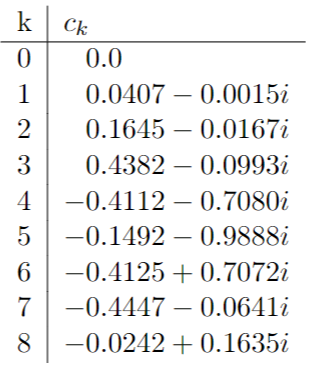

c = [0.0 0.0407-0.0015i 0.1645-0.0167i 0.4382-0.0993i -0.4112-0.7080i -0.1492-0.9888i -0.4125+0.7072i -0.4447-0.0641i -0.0242+0.1635i]

c =    0.0000 + 0.0000i   0.0407 - 0.0015i   0.1645 - 0.0167i   0.4382 - 0.0993i  -0.4112 - 0.7080i  -0.1492 - 0.9888i  -0.4125 + 0.7072i  -0.4447 - 0.0641i  -0.0242 + 0.1635i



m = length(c);
a = real(c);
b = imag(c);
a(2:end)

ans =     0.0407    0.1645    0.4382   -0.4112   -0.1492   -0.4125   -0.4447   -0.0242



syms x k; 
f_series(x) = (a(1)/2) + sum(a(2:end).*subs(cos(k.*x),k,1:m-1) + b(2:end).*subs(sin(k.*x),k,1:m-1)) % replace 8 inside 0:8 with m!

$$f\_series(x) = \frac{329\,\cos\left(2\,x\right)}{2000}+\frac{2191\,\cos\left(3\,x\right)}{5000}-\frac{257\,\cos\left(4\,x\right)}{625}-\frac{373\,\cos\left(5\,x\right)}{2500}-\frac{33\,\cos\left(6\,x\right)}{80}-\frac{4447\,\cos\left(7\,x\right)}{10000}-\frac{121\,\cos\left(8\,x\right)}{5000}-\frac{167\,\sin\left(2\,x\right)}{10000}-\frac{993\,\sin\left(3\,x\right)}{10000}-\frac{177\,\sin\left(4\,x\right)}{250}-\frac{618\,\sin\left(5\,x\right)}{625}+\frac{442\,\sin\left(6\,x\right)}{625}-\frac{641\,\sin\left(7\,x\right)}{10000}+\frac{327\,\sin\left(8\,x\right)}{2000}+\frac{407\,\cos\left(x\right)}{10000}-\frac{3\,\sin\left(x\right)}{2000}$$

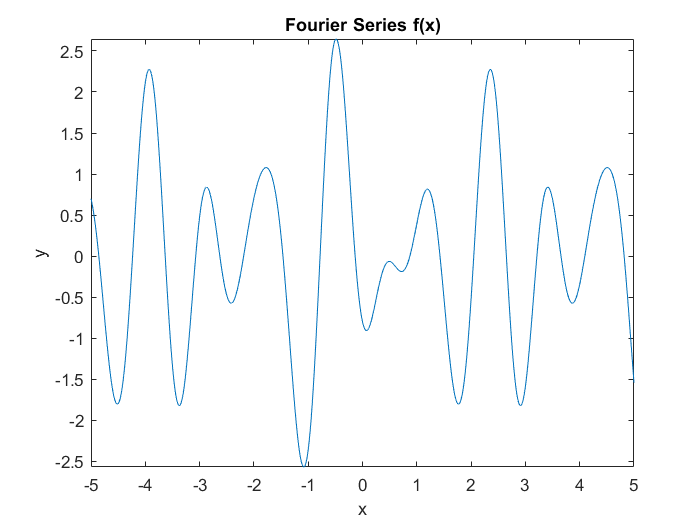


fplot(f_series)
title("Fourier Series f(x)")
xlabel("x"); ylabel("y");